problem1

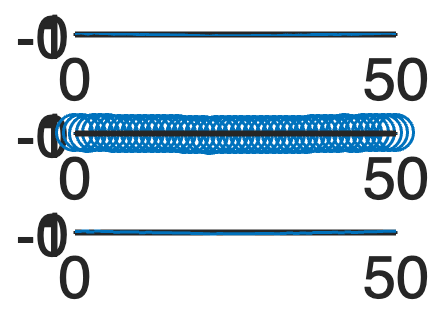

n = 0:50;
omega = sqrt(0.92) * randn(1, 51) + 0.2;
x = cos(0.04*pi*n) + 0.2 * omega;


figure(1);
subplot(3,1,1); plot(n,x);
subplot(3,1,2); stem(n,x);
subplot(3,1,3); stairs(n,x);

problem2

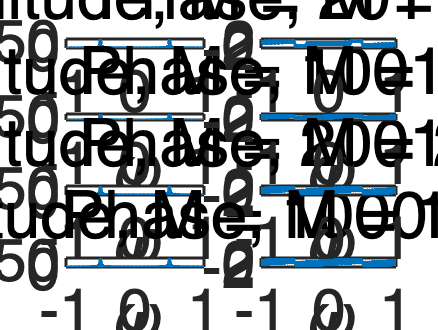

% 신호 정의
n = 0:100;
x = cos(pi/2 * n);

% 각 분해능
Ms = [201, 1001, 2001, 10001];

% 결과 저장용
X_all = cell(1,4);
w_all = cell(1,4);

% 반복 계산
for i = 1:4
    M = Ms(i);
    k = 0:M-1;
    w = -pi + (2*pi/M)*k;     % [-π, π] 범위
    X = x * exp(-1j * (n') * w);  % 행렬곱 기반 DTFT
    X_all{i} = X;
    w_all{i} = w/pi;
end

% 시각화: Magnitude 비교
figure;
for i = 1:4
    subplot(4,2,2*i-1);
    plot(w_all{i}, abs(X_all{i}));
    title(['Magnitude, M = ', num2str(Ms(i))]);
    xlabel('\omega'); ylabel('|X(e^{j\omega})|');
end

% 시각화: Phase 비교
for i = 1:4
    subplot(4,2,2*i);
    plot(w_all{i}, angle(X_all{i}));
    title(['Phase, M = ', num2str(Ms(i))]);
    xlabel('\omega'); ylabel('∠X(e^{j\omega})');
end

problem3

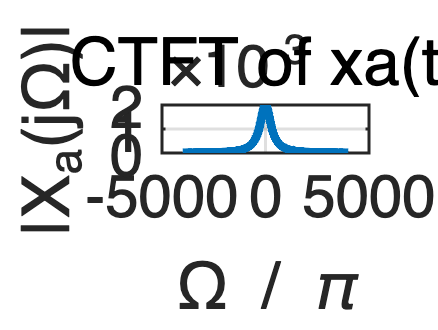

%% Problem 1 - 원래 연속시간 신호 정의 및 CTFT 근사
Dt = 0.00005;
t = -0.005:Dt:0.005;
xa = exp(-1000 * abs(t));  % 원래 신호

% CTFT 근사
Omega = linspace(-4000*pi, 4000*pi, 2000);
Xa = zeros(size(Omega));
for idx = 1:length(Omega)
    Xa(idx) = sum(xa .* exp(-1j * Omega(idx) * t)) * Dt;
end

% 시각화
figure;
plot(Omega / pi, abs(Xa), 'LineWidth', 1.5); grid on;
xlabel('\Omega / \pi'); ylabel('|X_a(j\Omega)|');
title('CTFT of xa(t)');

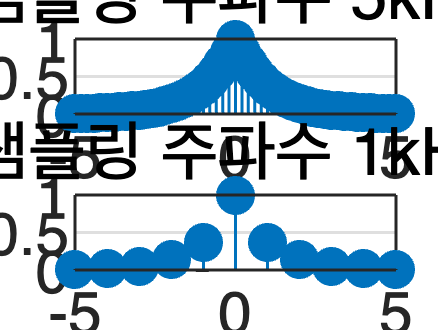


%% Problem 2 - 두 샘플링 주파수 (5kHz, 1kHz)로 이산화 및 DTFT
% 샘플링 조건
Ts1 = 0.0002; Fs1 = 1 / Ts1; n1 = -25:25; nTs1 = n1 * Ts1;
Ts2 = 0.001;  Fs2 = 1 / Ts2; n2 = -5:5;   nTs2 = n2 * Ts2;

x1 = exp(-1000 * abs(n1 * Ts1));
x2 = exp(-1000 * abs(n2 * Ts2));

% DTFT 계산
K = 500; k = -K:K; w = pi * k / K;
X1 = x1 * exp(-1j * n1' * w);
X2 = x2 * exp(-1j * n2' * w);

% 시각화: 이산 신호
figure;
subplot(2,1,1);
stem(n1 * Ts1 * 1000, x1, 'filled'); grid on;
xlabel('t [ms]'); ylabel('x_1[n]');
title('샘플링 주파수 5kHz');

subplot(2,1,2);
stem(n2 * Ts2 * 1000, x2, 'filled'); grid on;
xlabel('t [ms]'); ylabel('x_2[n]');
title('샘플링 주파수 1kHz');

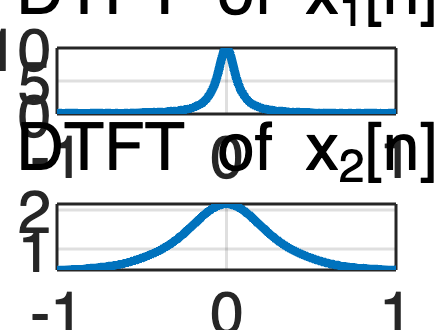


% 시각화: DTFT
figure;
subplot(2,1,1);
plot(w/pi, abs(X1), 'LineWidth', 1.5); grid on;
xlabel('\omega / \pi'); ylabel('|X_1(\omega)|');
title('DTFT of x_1[n]');

subplot(2,1,2);
plot(w/pi, abs(X2), 'LineWidth', 1.5); grid on;
xlabel('\omega / \pi'); ylabel('|X_2(\omega)|');
title('DTFT of x_2[n]');

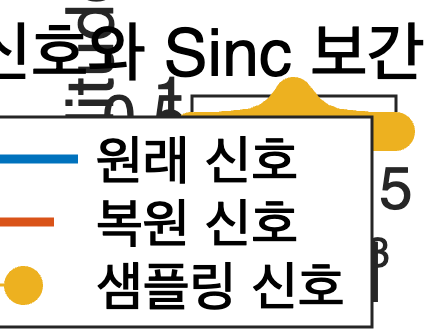


%% Problem 3 - Sinc 보간법으로 연속시간 신호 복원
% 고속 샘플링 (5kHz 기준)
Ts = 0.0002; Fs = 1 / Ts; n = -25:25; nTs = n * Ts;
x = exp(-1000 * abs(nTs));

% sinc 보간
xa_recon = x * sinc(Fs * (ones(length(nTs),1)*t - nTs'*ones(1,length(t))));

% 시각화
x_original = exp(-1000 * abs(t));

figure;
plot(t, x_original, 'LineWidth', 1.5); hold on;
plot(t, xa_recon, '--', 'LineWidth', 1.5);
stem(n*Ts, x, 'filled');
legend('원래 신호', '복원 신호', '샘플링 신호');
xlabel('t [sec]'); ylabel('Amplitude');
title('원 신호와 Sinc 보간 복원 비교');
grid on;